## 直進動作におけるオドメトリ評価

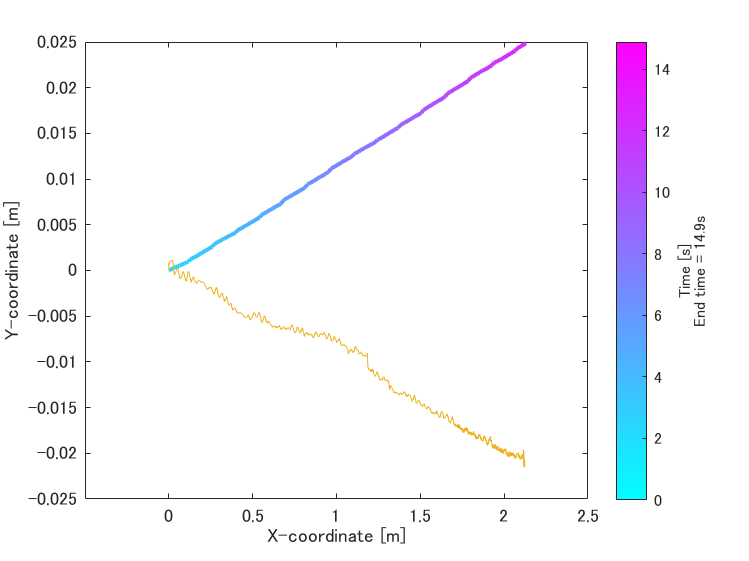

%Parameter
dataMatrix_sampling_Fs = 20;
dataMatrix2_sampling_Fs = 100;

% Function to read data from a CSV file
readCsv = @(filePath) readmatrix(filePath);

% File paths
csvFilePath = '1_roomba.csv';
csvFilePath2 = '1_motion.csv';

% Read data from CSV files
dataMatrix = readCsv(csvFilePath);
dataMatrix2 = readCsv(csvFilePath2);

% Extract data columns
time = (dataMatrix(:, 1) - dataMatrix(1, 1)) / 1000; % Time [s]
theta = dataMatrix(:, 4);     % Theta
vel = dataMatrix(:, 5);       % Velocity
omega = dataMatrix(:, 6);     % Angular velocity
enc_l = dataMatrix(:, 7);     % Encoder val
enc_r = dataMatrix(:, 8);


x = dataMatrix(:, 2);         % X-coordinate
y = dataMatrix(:, 3);         % Y-coordinate

true_time = dataMatrix2(:, 1) - dataMatrix2(1, 1);
true_x = dataMatrix2(:, 2) - dataMatrix2(1, 2);
true_y = dataMatrix2(:, 3) - dataMatrix2(1, 3);
true_theta = dataMatrix2(:, 4) - dataMatrix2(1, 4);

% Resampling
re_true_x = resample(true_x, dataMatrix_sampling_Fs, dataMatrix2_sampling_Fs);
re_true_y = resample(true_y, dataMatrix_sampling_Fs, dataMatrix2_sampling_Fs);
re_true_theta = resample(true_theta, dataMatrix_sampling_Fs, dataMatrix2_sampling_Fs);
re_true_time = resample(true_time, dataMatrix_sampling_Fs, dataMatrix2_sampling_Fs);

re_true_x = round(re_true_x*1000); %m2mm
re_true_y = round(re_true_y*1000);

cal_x = round(x*1000); %m2mm
cal_y = round(y*1000);


% Error rate calculation
Error_x = [];
Error_y = [];
Error_theta = [];
Error_x_time = [];
Error_y_time = [];
Error_theta_time = [];

for i = 1:length(time)
    if re_true_x(i) ~= 0
        Error_x(end+1, 1) = (re_true_x(i) - cal_x(i)) / re_true_x(end);     % / re_true_x(i)?
        Error_x_time(end+1, 1) = time(i);
    end

    if re_true_y(i) ~= 0 && cal_y(i) ~= 0
        Error_y(end+1, 1) = (re_true_y(i) - cal_y(i)) / re_true_y(end);     % / re_true_y(i)?
        Error_y_time(end+1, 1) = time(i);
    end

    if true_theta(i) ~= 0 && theta(i) ~= 0
        Error_theta(end+1, 1) = (true_theta(i) - theta(i)) / true_theta(end);     % / re_true_y(i)?
        Error_theta_time(end+1, 1) = time(i);
    end

end

Error_x = Error_x * 100; % Converted to percentage
Error_y = Error_y * 100;
Error_theta = Error_theta * 100;

% Plot trajectory
figure;
ax = gca;
hold(ax, 'on');
box on;

colormap('cool');
c = colormap;
color_steps = size(c, 1);

for i = 1:length(time)-1
    color_index = round((i-1)/(length(time)-1) * (color_steps-1)) + 1;
    line_color = c(color_index, :);
    
    plot(ax, [x(i), x(i+1)], [y(i), y(i+1)], 'Color', line_color, 'LineWidth', 2);
end

plot(ax, true_x, true_y)
xticks(ax,0:0.5:2.5)
yticks(ax,-0.03:0.005:0.03)
xlabel(ax, 'X-coordinate [m]');
ylabel(ax, 'Y-coordinate [m]');

clim(ax, [min(time), max(time)]);
hcb = colorbar;
xlabel(hcb, {'Time [s]', ['End time = ', num2str(round(max(time), 1)), 's']});
hold(ax, 'off');

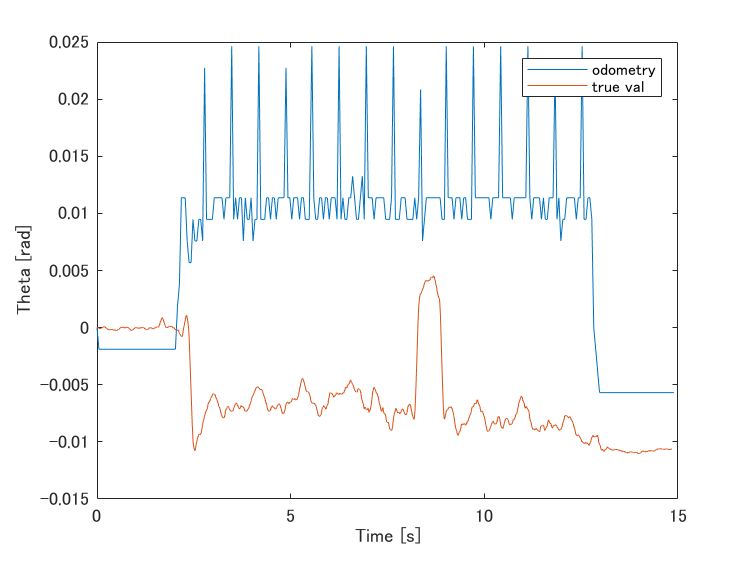


% Plot odometry and true values
figure;
ax = gca;
hold(ax, 'on');
box on;

plot(ax, time, theta, 'DisplayName', 'odometry')
plot(ax, true_time, true_theta, 'DisplayName', 'true val')
legend('Location', 'northeast');
xticks(ax,0:5:15);
yticks(ax,-0.015:0.005:0.03);
xlabel(ax, 'Time [s]');
ylabel(ax, 'Theta [rad]');
hold(ax, 'off');

% Plot error rate
box on;

plot(Error_x_time, Error_x, 'DisplayName', 'x error rate')
p = polyfit(Error_x_time,Error_x,3)

p =     0.0068   -0.1471    0.8225   -2.0985


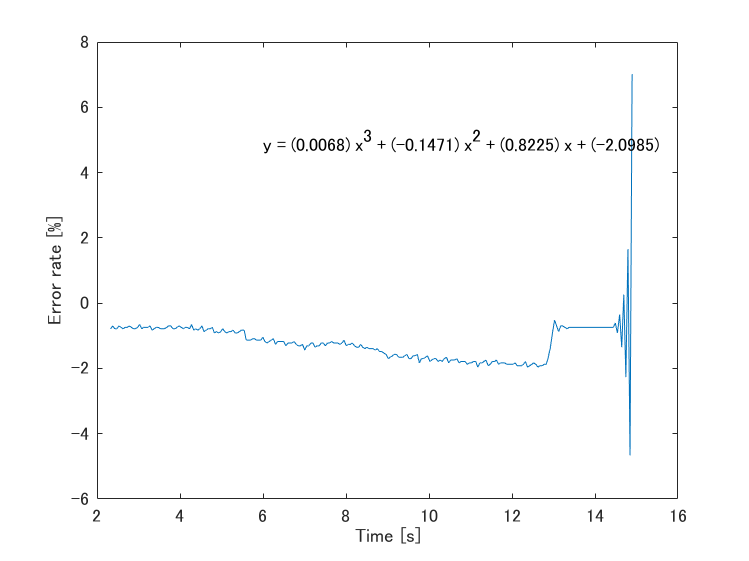

s = sprintf('y = (%.4f) x^3 + (%.4f) x^2 + (%.4f) x + (%.4f)',p(1),p(2),p(3),p(4));
text(6,5,s)
xlabel('Time [s]');
ylabel('Error rate [%]');

box on;

plot(Error_y_time, Error_y, 'DisplayName', 'y_error_rate')
p = polyfit(Error_y_time,Error_y,3)

p =    -0.1541    3.7660   -8.5851   14.2487


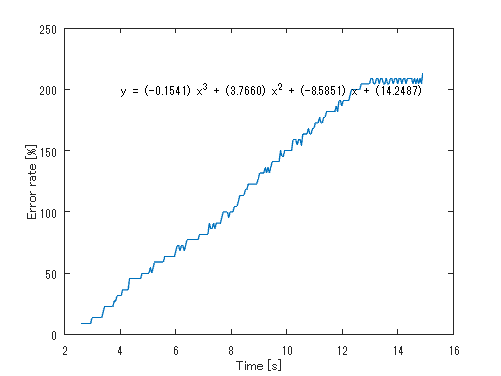

s = sprintf('y = (%.4f) x^3 + (%.4f) x^2 + (%.4f) x + (%.4f)',p(1),p(2),p(3),p(4));
text(4,200,s)
xlabel('Time [s]');
ylabel('Error rate [%]');

box on;

plot(Error_theta_time, Error_theta, 'DisplayName', 'theta_error_rate')
p = polyfit(Error_theta_time,Error_theta,3)

p =    -0.0020   -2.4226   39.9214  -33.9822


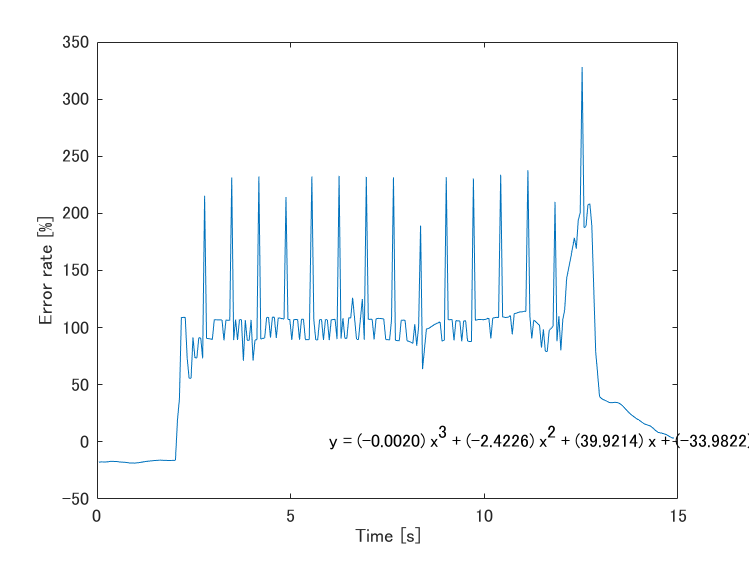

s = sprintf('y = (%.4f) x^3 + (%.4f) x^2 + (%.4f) x + (%.4f)',p(1),p(2),p(3),p(4));
text(6,5,s)
xlabel('Time [s]');
ylabel('Error rate [%]');

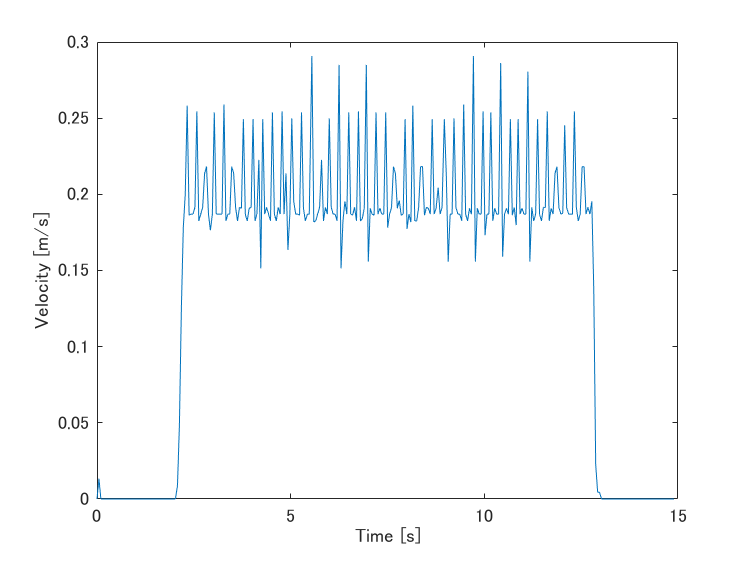


% Plot velocity and angular velocity
figure;
ax = gca;
hold(ax, 'on');
box on;

plot(ax, time, vel, 'DisplayName', 'Velocity')
xlabel(ax, 'Time [s]');
ylabel(ax, 'Velocity [m/s]');

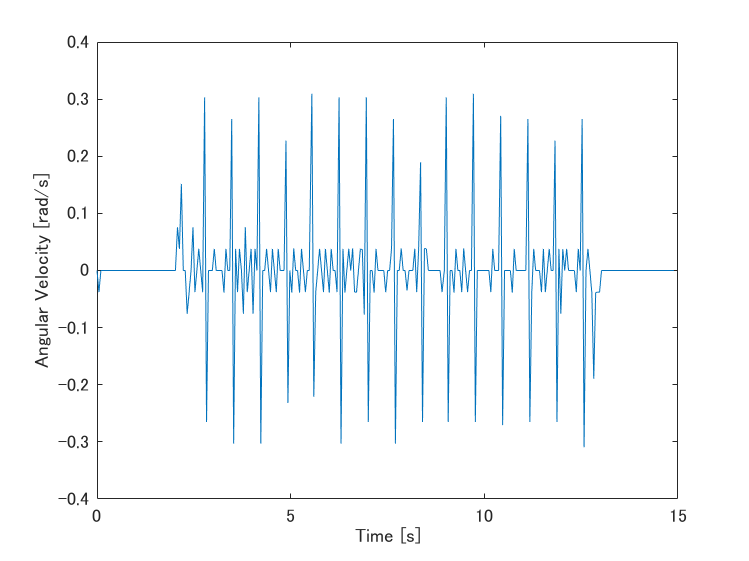

% legend('Location', 'northeast');

figure;
ax = gca;
hold(ax, 'on');
box on;

plot(ax, time, omega, 'DisplayName', 'Angular Velocity')
xlabel(ax, 'Time [s]');
ylabel(ax, 'Angular Velocity [rad/s]');

% legend('Location', 'northeast');

y = y*1000

y =          0
         0
   -0.0013
   -0.0013
   -0.0013
   -0.0013
   -0.0013
   -0.0013
   -0.0013
   -0.0013



y2 = y;
y2(1:55,:) = [];
y2(202:end,:) = [];


time2 = time;
time2(1:55,:) = [];
time2(202:end,:) = [];
time2 = time2 - time2(1,1)

time2 =          0
    0.0500
    0.1000
    0.1500
    0.2000
    0.2500
    0.3000
    0.3500
    0.4000
    0.4500



figure;
ax = gca;
hold(ax, 'on');
box on;
p = polyfit(time2,y2,1)

p =     2.3763    0.9312


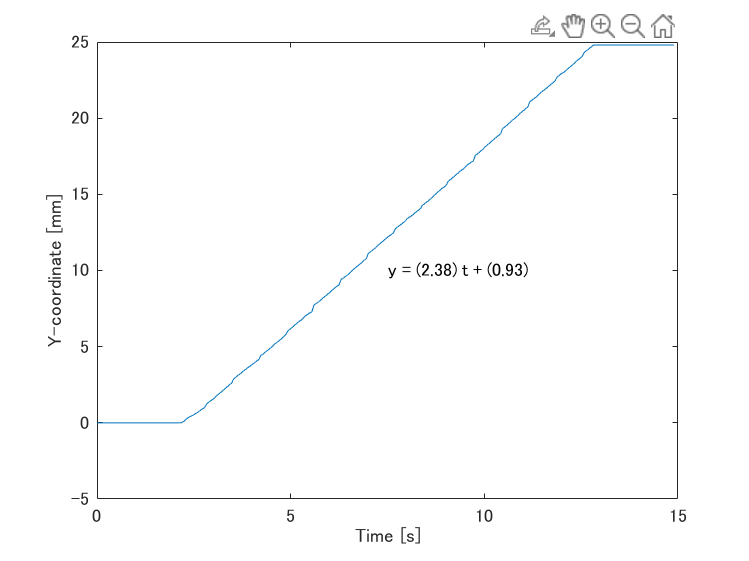

s = sprintf('y = (%.2f) t + (%.2f)',p(1),p(2));
text(7.5,10,s)
plot(ax, time,y, 'DisplayName', 'y Error')
xlabel(ax, 'Time [s]');
ylabel(ax, 'Y-coordinate [mm]');

## 緩旋回におけるオドメトリ評価

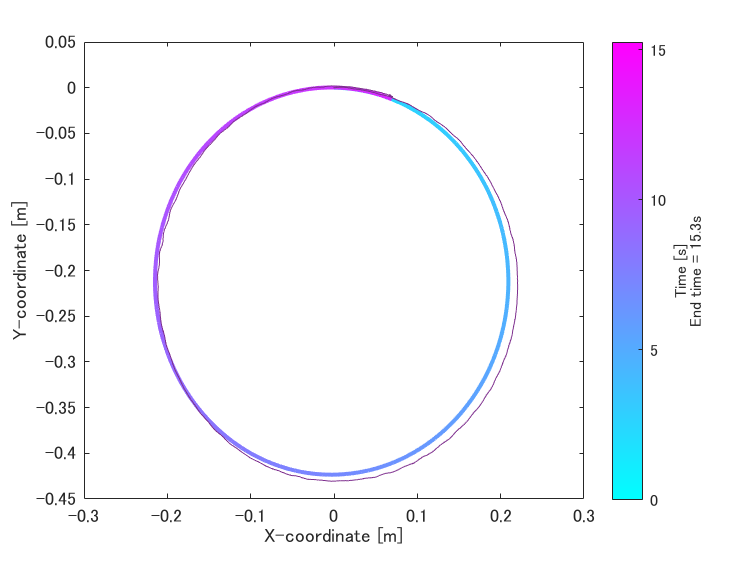

%Parameter
dataMatrix_sampling_Fs = 20;
dataMatrix2_sampling_Fs = 100;

% Function to read data from a CSV file
readCsv = @(filePath) readmatrix(filePath);

% File paths
csvFilePath = '2_2_roomba.csv';
csvFilePath2 = '2_2_motion.csv';

% Read data from CSV files
dataMatrix = readCsv(csvFilePath);
dataMatrix2 = readCsv(csvFilePath2);

% Extract data columns
time  = dataMatrix(:, 1) / 1000; % Time [s]
% time = (dataMatrix(:, 1) - dataMatrix(1, 1)) / 1000 % Time [s]
theta = dataMatrix(:, 4);     % Theta
vel = dataMatrix(:, 5);       % Velocity
omega = dataMatrix(:, 6);     % Angular velocity
enc_l = dataMatrix(:, 7);     % Encoder val
enc_r = dataMatrix(:, 8);


x = dataMatrix(:, 2);         % X-coordinate
y = dataMatrix(:, 3);         % Y-coordinate

true_time = dataMatrix2(:, 1) - dataMatrix2(1, 1);
true_x = dataMatrix2(:, 2) - dataMatrix2(1, 2);
true_y = dataMatrix2(:, 3) - dataMatrix2(1, 3);
true_theta = dataMatrix2(:, 4) - dataMatrix2(1, 4);

% Resampling
re_true_x = resample(true_x, dataMatrix_sampling_Fs, dataMatrix2_sampling_Fs);
re_true_y = resample(true_y, dataMatrix_sampling_Fs, dataMatrix2_sampling_Fs);
re_true_theta = resample(true_theta, dataMatrix_sampling_Fs, dataMatrix2_sampling_Fs);
re_true_time = resample(true_time, dataMatrix_sampling_Fs, dataMatrix2_sampling_Fs);

re_true_x = round(re_true_x*1000); %m2mm
re_true_y = round(re_true_y*1000);

cal_x = round(x*1000); %m2mm
cal_y = round(y*1000);


% Error rate calculation
Error_x = [];
Error_y = [];
Error_theta = [];
Error_x_time = [];
Error_y_time = [];
Error_theta_time = [];

for i = 1:length(time)-1
    if re_true_x(i) ~= 0 && cal_x(i) ~= 0
        Error_x(end+1, 1) = (re_true_x(i) - cal_x(i)) / re_true_x(end);     % / re_true_x(i)?
        Error_x_time(end+1, 1) = time(i);
    end

    if re_true_y(i) ~= 0 && cal_y(i) ~= 0
        Error_y(end+1, 1) = (re_true_y(i) - cal_y(i)) / re_true_y(end);     % / re_true_y(i)?
        Error_y_time(end+1, 1) = time(i);
    end

    if true_theta(i) ~= 0 && theta(i) ~= 0
        Error_theta(end+1, 1) = (true_theta(i) - theta(i)) / true_theta(i);     % / re_true_y(i)?
        Error_theta_time(end+1, 1) = time(i);
    end

end

Error_x = abs(Error_x) * 100; % Converted to percentage
Error_y = abs(Error_y) * 100;
Error_theta = abs(Error_theta) * 100;

% Plot trajectory
figure;
ax = gca;
hold(ax, 'on');
box on;

colormap('cool');
c = colormap;
color_steps = size(c, 1);

for i = 1:length(time)-1
    color_index = round((i-1)/(length(time)-1) * (color_steps-1)) + 1;
    line_color = c(color_index, :);
    
    plot(ax, [x(i), x(i+1)], [y(i), y(i+1)], 'Color', line_color, 'LineWidth', 2);
end

plot(ax, true_x, true_y)
xlabel(ax, 'X-coordinate [m]');
ylabel(ax, 'Y-coordinate [m]');

clim(ax, [min(time), max(time)]);
hcb = colorbar;
xlabel(hcb, {'Time [s]', ['End time = ', num2str(round(max(time), 1)), 's']});
hold(ax, 'off');

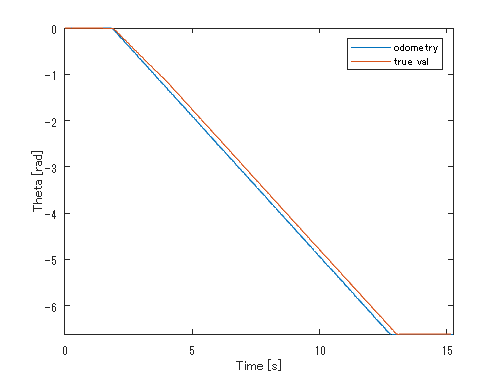


% Plot odometry and true values
figure;
ax = gca;
hold(ax, 'on');
box on;

plot(ax, time, theta, 'DisplayName', 'odometry')
plot(ax, true_time, true_theta, 'DisplayName', 'true val')
legend('Location', 'northeast');
xlabel(ax, 'Time [s]');
ylabel(ax, 'Theta [rad]');
hold(ax, 'off');

% Plot error rate
box on;

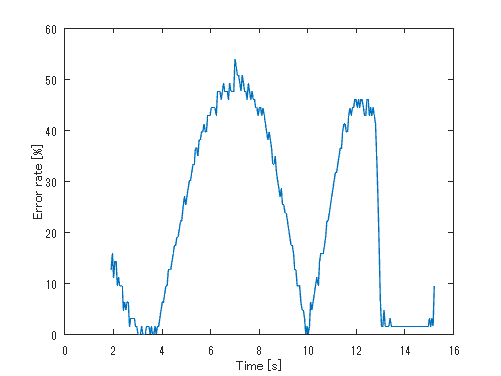

plot(Error_x_time, Error_x, 'DisplayName', 'x error rate')
xlabel('Time [s]');
ylabel('Error rate [%]');

box on;

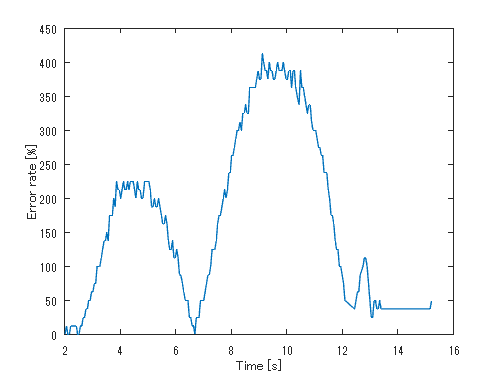

plot(Error_y_time, Error_y, 'DisplayName', 'y_error_rate')
xlabel('Time [s]');
ylabel('Error rate [%]');

box on;

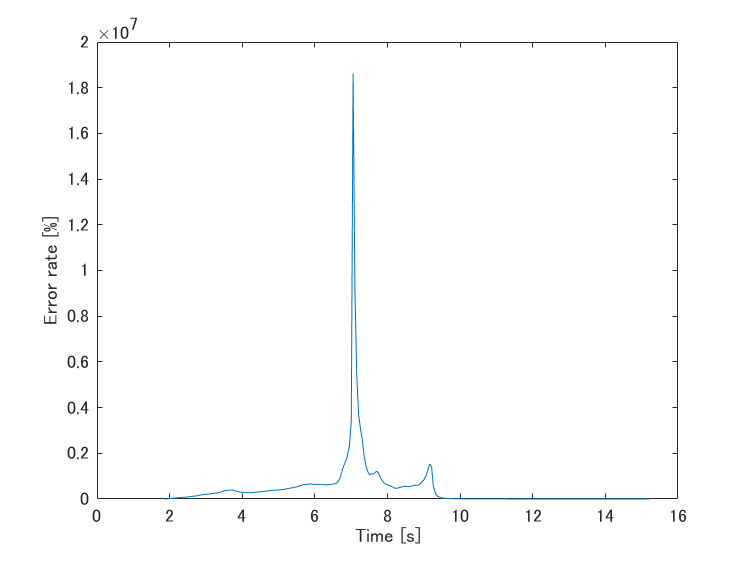

plot(Error_theta_time, Error_theta, 'DisplayName', 'theta_error_rate')
xlabel('Time [s]');
ylabel('Error rate [%]');

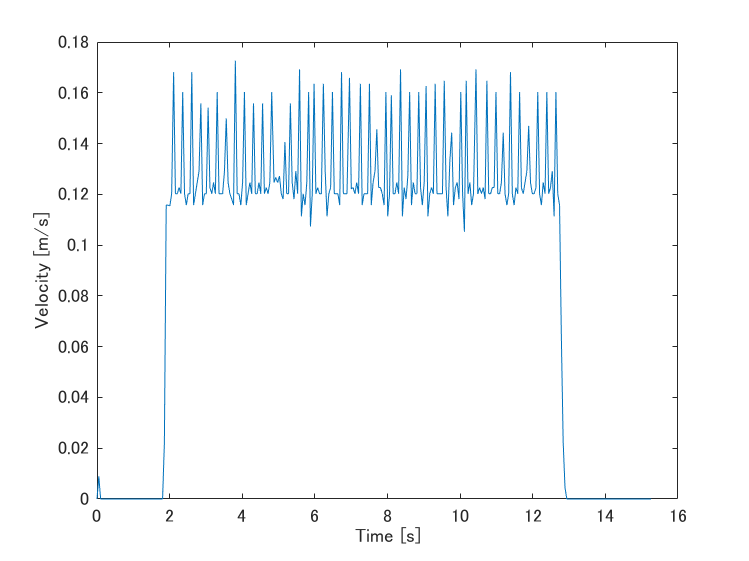


% Plot velocity and angular velocity
figure;
ax = gca;
hold(ax, 'on');
box on;

plot(ax, time, vel, 'DisplayName', 'Velocity')
xlabel(ax, 'Time [s]');
ylabel(ax, 'Velocity [m/s]');

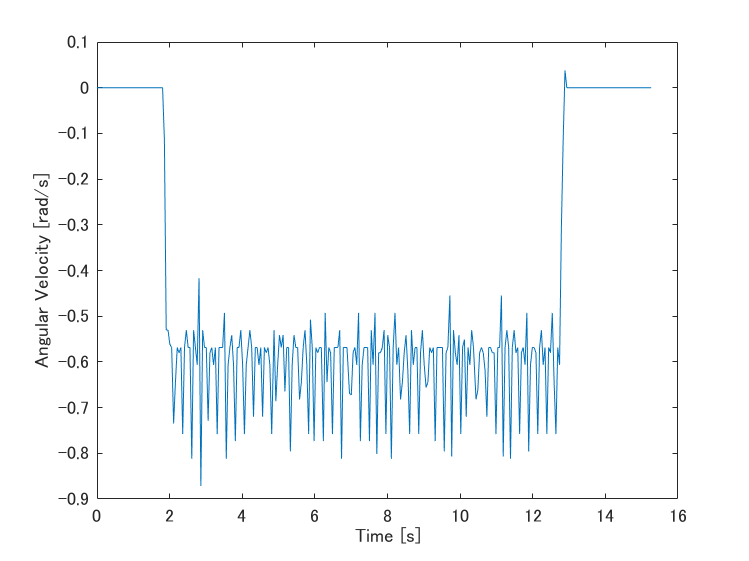

% legend('Location', 'northeast');

figure;
ax = gca;
hold(ax, 'on');
box on;

plot(ax, time, omega, 'DisplayName', 'Angular Velocity')
xlabel(ax, 'Time [s]');
ylabel(ax, 'Angular Velocity [rad/s]');

% legend('Location', 'northeast');

## 四角経路走行におけるオドメトリ評価

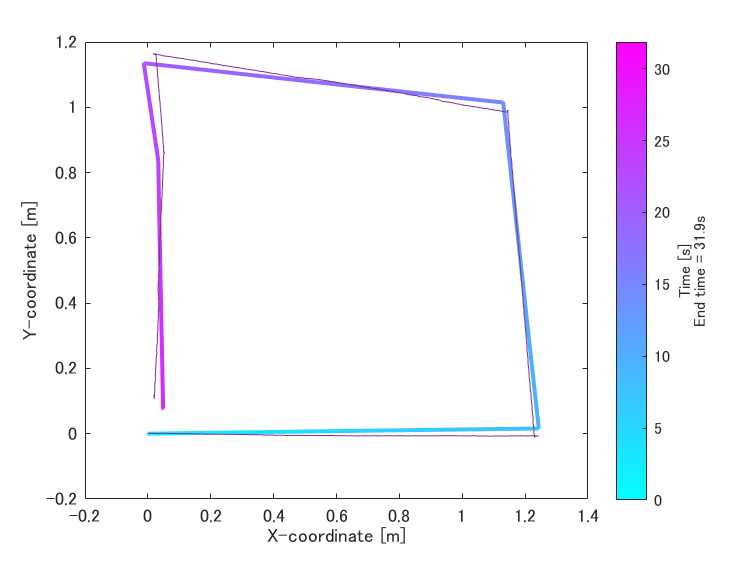

%Parameter
dataMatrix_sampling_Fs = 20;
dataMatrix2_sampling_Fs = 100;

% Function to read data from a CSV file
readCsv = @(filePath) readmatrix(filePath);

% File paths
csvFilePath = '3_roomba.csv';
csvFilePath2 = '3_motion.csv';

% Read data from CSV files
dataMatrix = readCsv(csvFilePath);
dataMatrix2 = readCsv(csvFilePath2);

% Extract data columns
time = (dataMatrix(:, 1) - dataMatrix(1, 1))/1000; % Time [s]
theta = dataMatrix(:, 4);     % Theta
vel = dataMatrix(:, 5);       % Velocity
omega = dataMatrix(:, 6);     % Angular velocity
enc_l = dataMatrix(:, 7);     % Encoder val
enc_r = dataMatrix(:, 8);


x = dataMatrix(:, 2);         % X-coordinate
y = dataMatrix(:, 3);         % Y-coordinate

true_time = dataMatrix2(:, 1) - dataMatrix2(1, 1);
true_x = dataMatrix2(:, 2) - dataMatrix2(1, 2);
true_y = dataMatrix2(:, 3) - dataMatrix2(1, 3);
true_theta = dataMatrix2(:, 4) - dataMatrix2(1, 4);

% Resampling
re_true_x = resample(true_x, dataMatrix_sampling_Fs, dataMatrix2_sampling_Fs);
re_true_y = resample(true_y, dataMatrix_sampling_Fs, dataMatrix2_sampling_Fs);
re_true_theta = resample(true_theta, dataMatrix_sampling_Fs, dataMatrix2_sampling_Fs);
re_true_time = resample(true_time, dataMatrix_sampling_Fs, dataMatrix2_sampling_Fs);

re_true_x = round(re_true_x*1000); %m2mm
re_true_y = round(re_true_y*1000);

cal_x = round(x*1000); %m2mm
cal_y = round(y*1000);


% Error rate calculation
Error_x = [];
Error_y = [];
Error_theta = [];
Error_x_time = [];
Error_y_time = [];
Error_theta_time = [];

for i = 1:length(time)
    if re_true_x(i) ~= 0
        Error_x(end+1, 1) = (re_true_x(i) - cal_x(i)) / re_true_x(i);     % / re_true_x(i)?
        Error_x_time(end+1, 1) = time(i);
    end

    if re_true_y(i) ~= 0 && cal_y(i) ~= 0
        Error_y(end+1, 1) = (re_true_y(i) - cal_y(i)) / re_true_y(i);     % / re_true_y(i)?
        Error_y_time(end+1, 1) = time(i);
    end

    if true_theta(i) ~= 0 && theta(i) ~= 0
        Error_theta(end+1, 1) = (true_theta(i) - theta(i)) / true_theta(i);     % / re_true_y(i)?
        Error_theta_time(end+1, 1) = time(i);
    end

end

Error_x = abs(Error_x) * 100; % Converted to percentage
Error_y = abs(Error_y) * 100;
Error_theta = Error_theta * 100;

% Plot trajectory
figure;
ax = gca;
hold(ax, 'on');
box on;

colormap('cool');
c = colormap;
color_steps = size(c, 1);

for i = 1:length(time)-1
    color_index = round((i-1)/(length(time)-1) * (color_steps-1)) + 1;
    line_color = c(color_index, :);
    
    plot(ax, [x(i), x(i+1)], [y(i), y(i+1)], 'Color', line_color, 'LineWidth', 2);
end

plot(ax, true_x, true_y)
xlabel(ax, 'X-coordinate [m]');
ylabel(ax, 'Y-coordinate [m]');

clim(ax, [min(time), max(time)]);
hcb = colorbar;
xlabel(hcb, {'Time [s]', ['End time = ', num2str(round(max(time), 1)), 's']});
hold(ax, 'off');

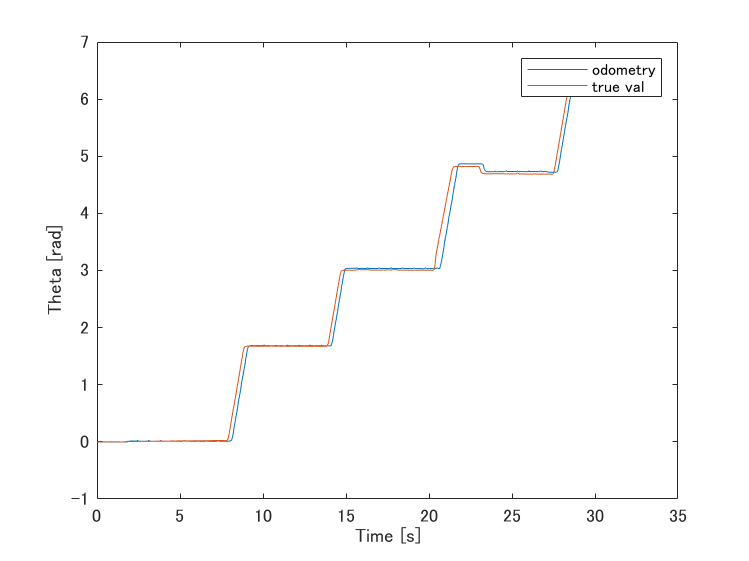


% Plot odometry and true values
figure;
ax = gca;
hold(ax, 'on');
box on;

plot(ax, time, theta, 'DisplayName', 'odometry')
plot(ax, true_time, true_theta, 'DisplayName', 'true val')
legend('Location', 'northeast');
xlabel(ax, 'Time [s]');
ylabel(ax, 'Theta [rad]');
hold(ax, 'off');

% Plot error rate
box on;

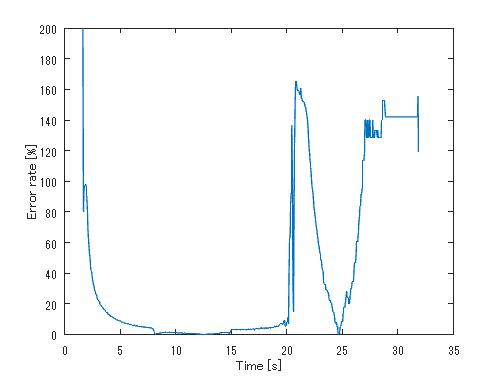

plot(Error_x_time, Error_x, 'DisplayName', 'x error rate')
xlabel('Time [s]');
ylabel('Error rate [%]');

box on;

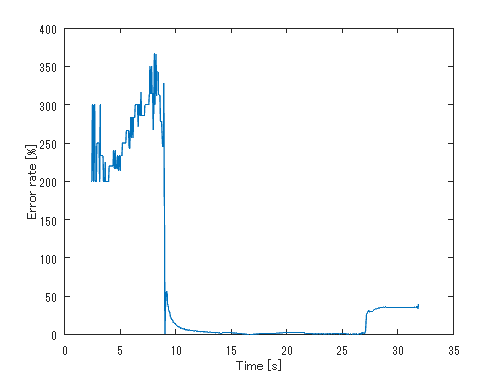

plot(Error_y_time, Error_y, 'DisplayName', 'y_error_rate')
xlabel('Time [s]');
ylabel('Error rate [%]');

box on;

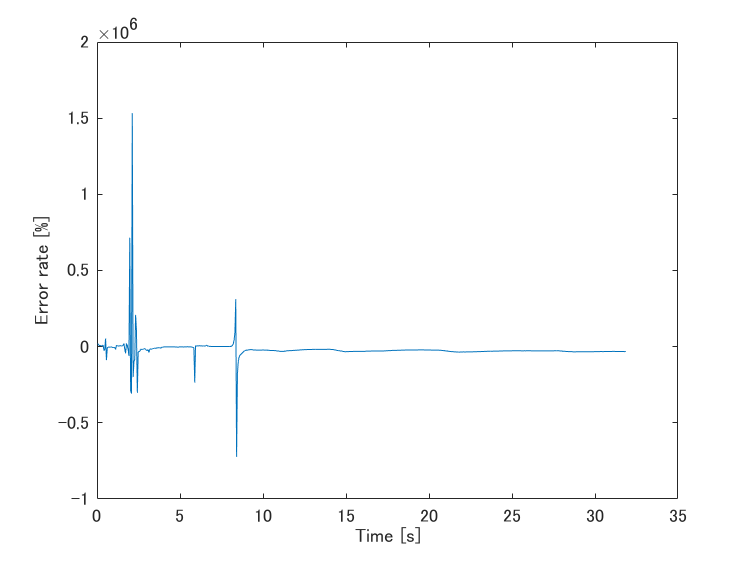

plot(Error_theta_time, Error_theta, 'DisplayName', 'theta_error_rate')
xlabel('Time [s]');
ylabel('Error rate [%]');

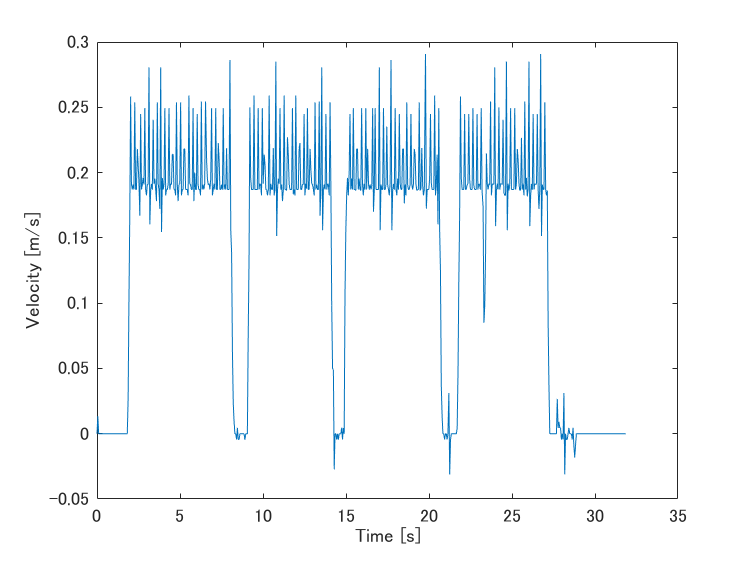


% Plot velocity and angular velocity
figure;
ax = gca;
hold(ax, 'on');
box on;

plot(ax, time, vel, 'DisplayName', 'Velocity')
xlabel(ax, 'Time [s]');
ylabel(ax, 'Velocity [m/s]');

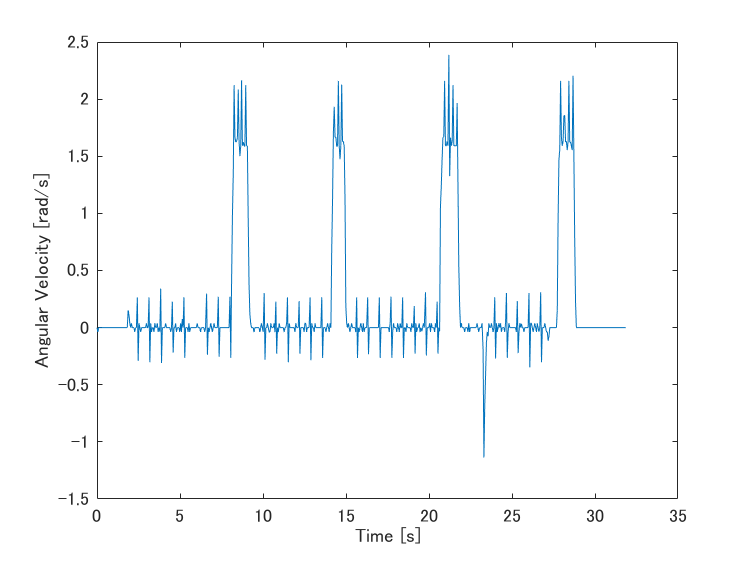

% legend('Location', 'northeast');

figure;
ax = gca;
hold(ax, 'on');
box on;

plot(ax, time, omega, 'DisplayName', 'Angular Velocity')
xlabel(ax, 'Time [s]');
ylabel(ax, 'Angular Velocity [rad/s]');

% legend('Location', 'northeast');

## 超信地旋回におけるオドメトリ評価

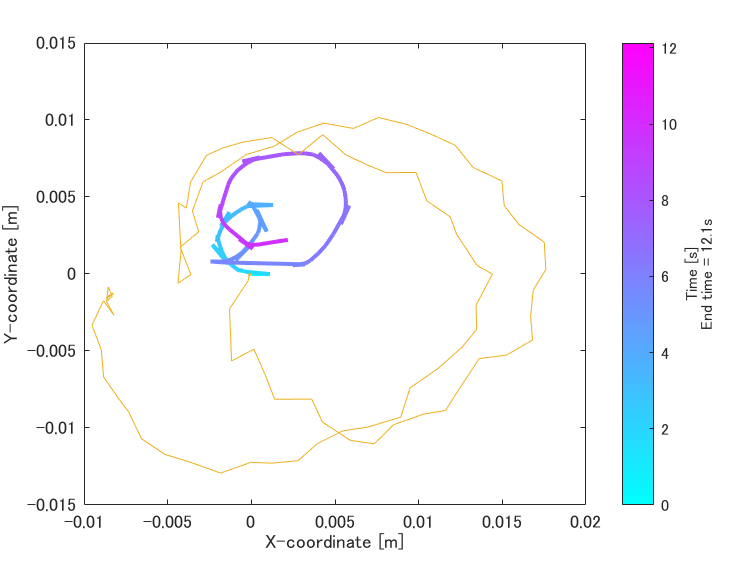

%Parameter
dataMatrix_sampling_Fs = 20;
dataMatrix2_sampling_Fs = 10;

% Function to read data from a CSV file
readCsv = @(filePath) readmatrix(filePath);

% File paths
csvFilePath = '4_2_roomba.csv';
csvFilePath2 = '4_2_motion.csv';

% Read data from CSV files
dataMatrix = readCsv(csvFilePath);
dataMatrix2 = readCsv(csvFilePath2);

% Extract data columns
time = (dataMatrix(:, 1) - dataMatrix(1, 1)); % Time [s]
theta = dataMatrix(:, 4);     % Theta
vel = dataMatrix(:, 5);       % Velocity
omega = dataMatrix(:, 6);     % Angular velocity
enc_l = dataMatrix(:, 7);     % Encoder val
enc_r = dataMatrix(:, 8);

x = dataMatrix(:, 2);         % X-coordinate
y = dataMatrix(:, 3);         % Y-coordinate

true_time = dataMatrix2(:, 1) - dataMatrix2(1, 1);
true_x = dataMatrix2(:, 2) - dataMatrix2(1, 2);
true_y = dataMatrix2(:, 3) - dataMatrix2(1, 3);
true_theta = dataMatrix2(:, 4) - dataMatrix2(1, 4);

% Resampling
cal_x = resample(x, dataMatrix2_sampling_Fs, dataMatrix_sampling_Fs);
cal_y = resample(y, dataMatrix2_sampling_Fs, dataMatrix_sampling_Fs);
cal_theta = resample(theta, dataMatrix2_sampling_Fs, dataMatrix_sampling_Fs);
cal_time = resample(time, dataMatrix2_sampling_Fs, dataMatrix_sampling_Fs);

cal_x = round(cal_x*1000); %m2mm
cal_y = round(cal_y*1000);

re_true_x = round(true_x*1000); %m2mm
re_true_y = round(true_y*1000);

% prepare
cal_theta_1 = cal_theta;
cal_theta_2 = cal_theta;

cal_theta_1(59:end,:)=[];
cal_theta_2(1:58,:)=[];

true_theta_1 = true_theta;
true_theta_2 = true_theta;

true_theta_1(59:end,:)=[];
true_theta_2(1:58,:)=[];

cal_time_1 = cal_time;
cal_time_2 = cal_time;

cal_time_1(59:end,:)=[];
cal_time_2(1:58,:)=[];
cal_time_2(end,:)=[];

% Error rate calculation
Error_x = [];
Error_y = [];
Error_theta = [];
Error_theta_1 = [];
Error_theta_2 = [];
Error_x_time = [];
Error_y_time = [];
Error_theta_time = [];
Error_theta_time_1 = [];
Error_theta_time_2 = [];

for i = 1:length(cal_time)
    if re_true_x(i) ~= 0
        Error_x(end+1, 1) = (re_true_x(i) - cal_x(i)) / re_true_x(i);     % / re_true_x(i)?
        Error_x_time(end+1, 1) = time(i);
    end

    if re_true_y(i) ~= 0 && cal_y(i) ~= 0
        Error_y(end+1, 1) = (re_true_y(i) - cal_y(i)) / re_true_y(i);     % / re_true_y(i)?
        Error_y_time(end+1, 1) = time(i);
    end

    if true_theta(i) ~= 0 && cal_theta(i) ~= 0
        Error_theta(end+1, 1) = (true_theta(i) - cal_theta(i)) / true_theta(i);     % / re_true_y(i)?
        Error_theta_time(end+1, 1) = time(i);
    end
end

for i = 1:length(cal_time_1)
    if true_theta_1(i) ~= 0 && cal_theta_1(i) ~= 0
        Error_theta_1(end+1, 1) = (true_theta_1(i) - cal_theta_1(i)) / true_theta_1(end);     % / re_true_y(i)?
        Error_theta_time_1(end+1, 1) = cal_time_1(i);
    end
end

for i = 1:length(cal_time_2)
    if true_theta_2(i) ~= 0 && cal_theta_2(i) ~= 0
        Error_theta_2(end+1, 1) = (true_theta_2(i) - cal_theta_2(i)) / true_theta_2(end);     % / re_true_y(i)?
        Error_theta_time_2(end+1, 1) = cal_time_2(i);
    end
end


Error_x = abs(Error_x) * 100; % Converted to percentage
Error_y = abs(Error_y) * 100;
Error_theta = abs(Error_theta) * 100;
Error_theta_1 = Error_theta_1 * 100;
Error_theta_2 = Error_theta_2 * 100;

% Plot trajectory
figure;
ax = gca;
hold(ax, 'on');
box on;

colormap('cool');
c = colormap;
color_steps = size(c, 1);

for i = 1:length(time)-1
    color_index = round((i-1)/(length(time)-1) * (color_steps-1)) + 1;
    line_color = c(color_index, :);
    
    plot(ax, [x(i), x(i+1)], [y(i), y(i+1)], 'Color', line_color, 'LineWidth', 2);
end

plot(ax, true_x, true_y)
xlabel(ax, 'X-coordinate [m]');
ylabel(ax, 'Y-coordinate [m]');

clim(ax, [min(time), max(time)]);
hcb = colorbar;
xlabel(hcb, {'Time [s]', ['End time = ', num2str(round(max(time), 1)), 's']});
hold(ax, 'off');

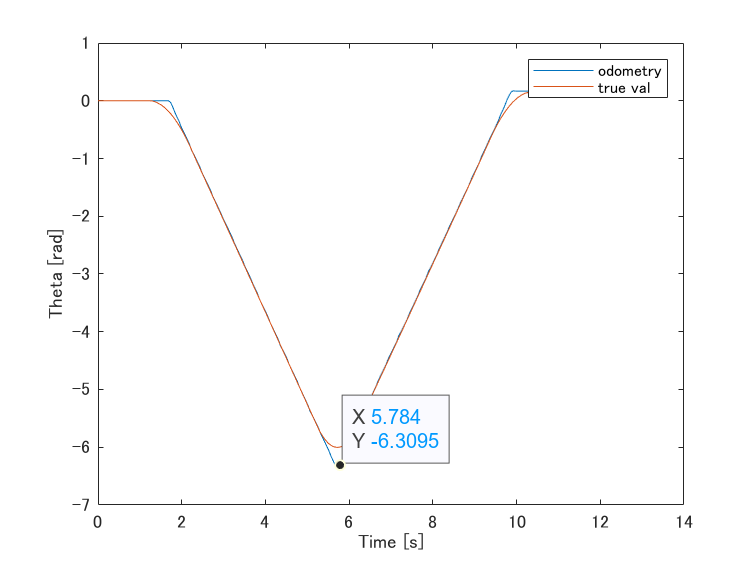


% Plot odometry and true values
figure;
ax = gca;
hold(ax, 'on');
box on;

plot(ax, time, theta, 'DisplayName', 'odometry')
plot(ax, true_time, true_theta, 'DisplayName', 'true val')
legend('Location', 'northeast');
xlabel(ax, 'Time [s]');
ylabel(ax, 'Theta [rad]');
hold(ax, 'off');

% Plot error rate
% fprintf('x error rate');
% box on;
% plot(Error_x_time, Error_x, 'DisplayName', 'x error rate')
% xlabel('Time [s]');
% ylabel('Error rate [%]');
% 
% fprintf('y error rate');
% box on;
% plot(Error_y_time, Error_y, 'DisplayName', 'y_error_rate')
% xlabel('Time [s]');
% ylabel('Error rate [%]');


% fprintf('theta error rate');
box on;

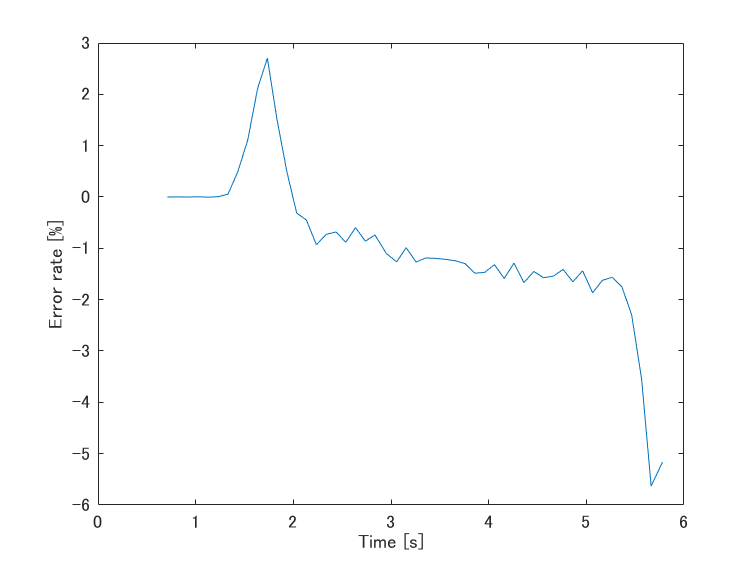

plot(Error_theta_time_1, Error_theta_1, 'DisplayName', 'theta_error_rate')
xlabel('Time [s]');
ylabel('Error rate [%]');

box on;

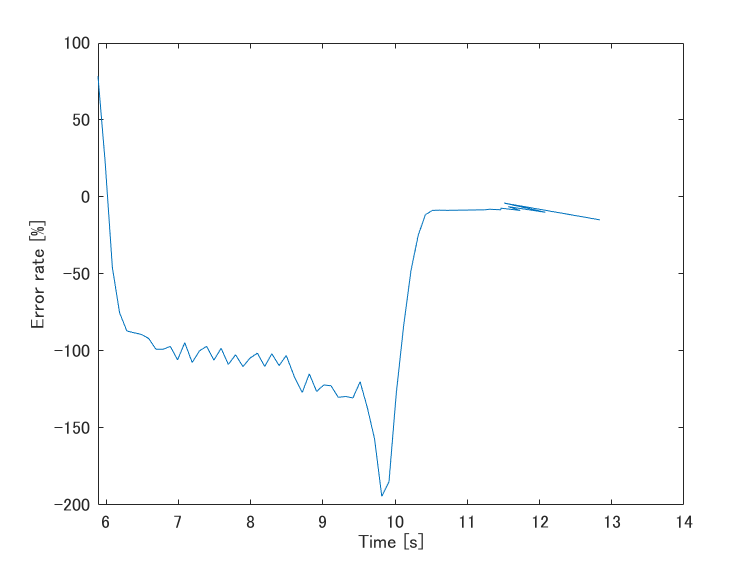

plot(Error_theta_time_2, Error_theta_2, 'DisplayName', 'theta_error_rate')
xlabel('Time [s]');
ylabel('Error rate [%]');

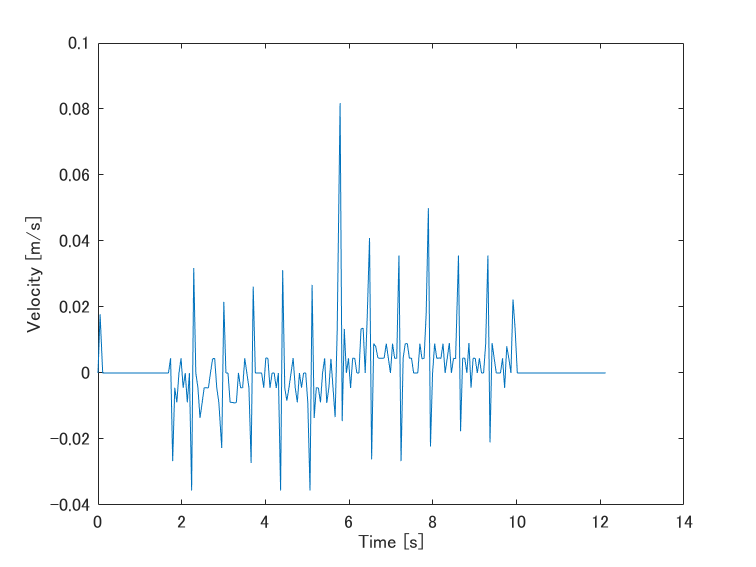


% fprintf('theta error rate');
% box on;
% plot(Error_theta_time, Error_theta, 'DisplayName', 'theta_error_rate')
% xlabel('Time [s]');
% ylabel('Error rate [%]');

% Plot velocity and angular velocity
figure;
ax = gca;
hold(ax, 'on');
box on;

plot(ax, time, vel, 'DisplayName', 'Velocity')
xlabel(ax, 'Time [s]');
ylabel(ax, 'Velocity [m/s]');

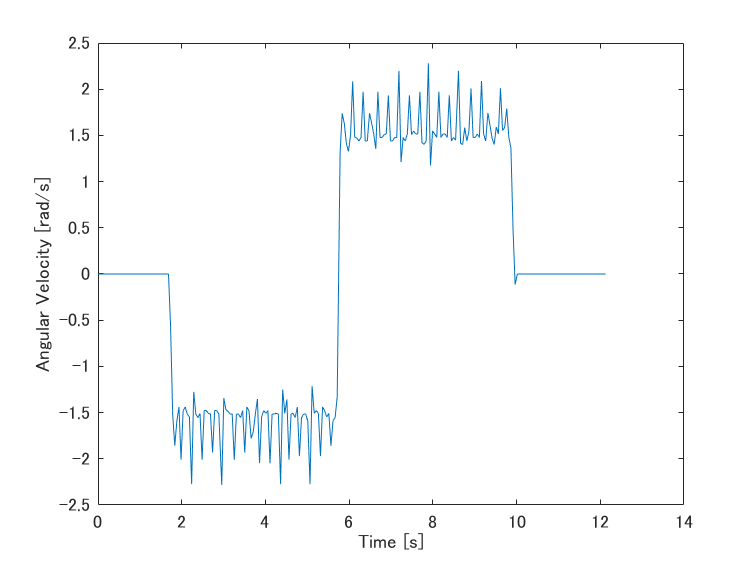

% legend('Location', 'northeast');

figure;
ax = gca;
hold(ax, 'on');
box on;

plot(ax, time, omega, 'DisplayName', 'Angular Velocity')
xlabel(ax, 'Time [s]');
ylabel(ax, 'Angular Velocity [rad/s]');

% legend('Location', 'northeast');